clear all;
clc;
load("ECG_with_noise.mat")
fs = 500;
time = (0 : length(nECG)-1)/fs;

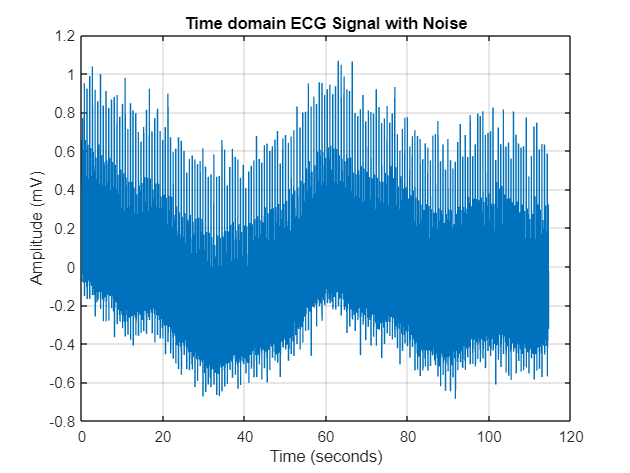

% Time domain signal
figure;
plot(time, nECG)
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Time domain ECG Signal with Noise');
grid on; 

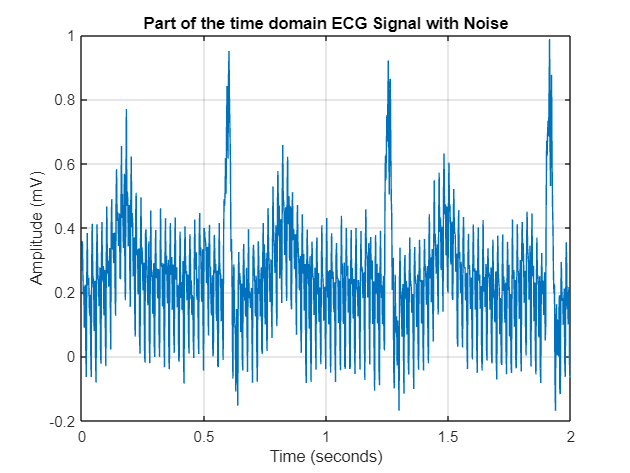


figure;
plot(time(1:1000), nECG(1:1000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Part of the time domain ECG Signal with Noise');
grid on; 

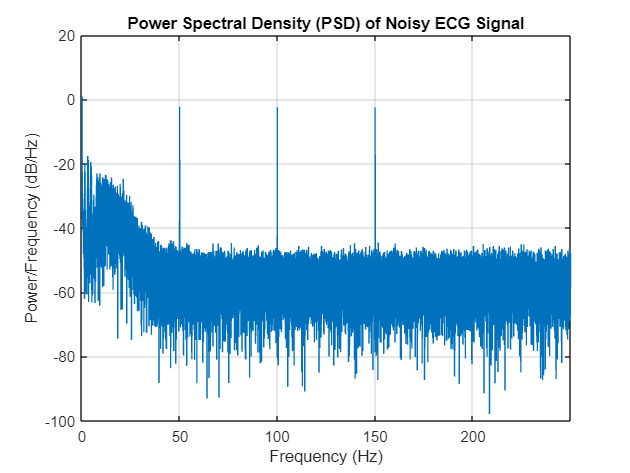

% Plot the Power Spectral Density (PSD)
% Define a rectangular window 
window = rectwin(length(nECG));  % Length equal to the signal length
nfft = length(nECG);  % FFT points (same as the length of the signal)

% Plot the frequency spectrum (PSD)
figure;
periodogram(nECG, window, nfft, fs); 
title('Power Spectral Density (PSD) of Noisy ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

% Passband and stop band ripple
delta = 0.005;

% The frequency range for an electrocardiogram (ECG) is typically 0.05 to 150 Hz

% High pass filter
fh_bp = 1.5;
fh_bs = 0.05;

% Low pass filter
fl_bp = 125;
fl_bs = 155;

% Required filter order and beta fpr Kaiser window
[n_h, Wn_h, beta_h, ftype_h] = kaiserord([fh_bs fh_bp], [0 1], [delta delta], fs);
[n_l, Wn_l, beta_l, ftype_l] = kaiserord([fl_bp fl_bs], [1 0], [delta delta], fs);
fprintf('High pass filter order = %d, Beta = %d ',n_h, beta_h);

High pass filter order = 916, Beta = 4.090904e+00 

fprintf('Low pass filter order = %d and Beta = %d ',n_l, beta_l);

Low pass filter order = 45 and Beta = 4.090904e+00 

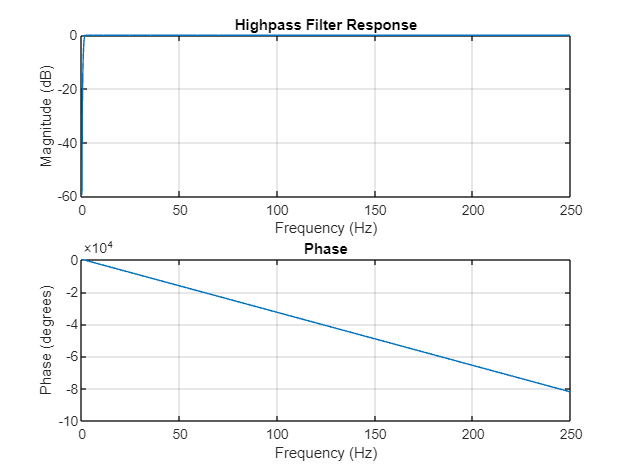


% Create the filters
b_high = fir1(n_h, Wn_h, ftype_h, kaiser(n_h+1, beta_h)); % numerator coeff. (High Pass)
b_low = fir1(n_l, Wn_l, ftype_l, kaiser(n_l+1, beta_l)); % numerator coeff. (Low Pass)
a_high = 1; % denominator coeff. (High Pass)
a_low = 1;% denominator coeff. (Low Pas)

% Visualize the highpass filter
figure;
freqz(b_high, a_high, 1024, fs);
title('Highpass Filter Response');

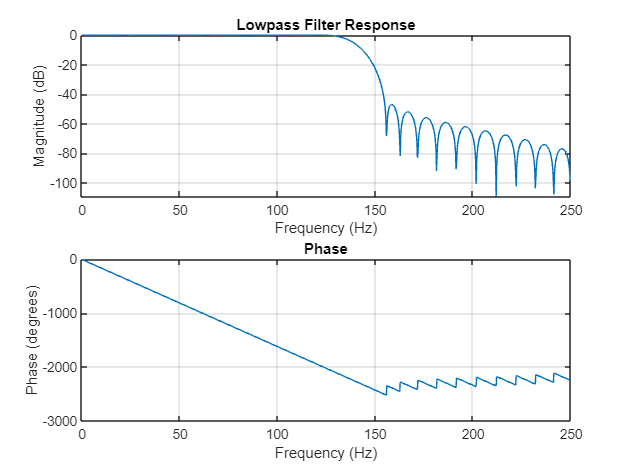



% Visualize the lowpass filter
figure;
freqz(b_low, a_low, 1024, fs);
title('Lowpass Filter Response');

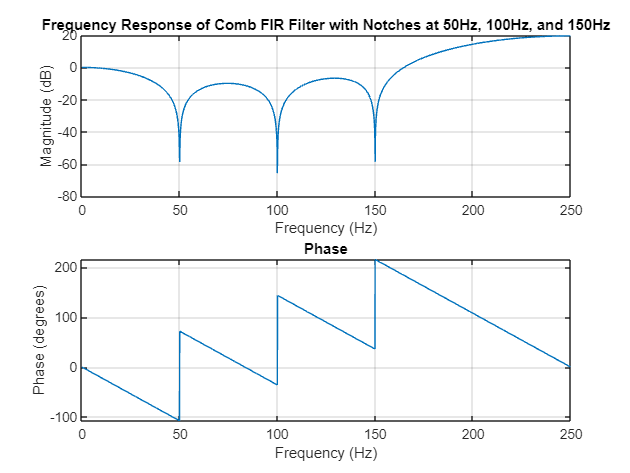

% Design Comb Filter

% Parameters
f1 = 50;   % First notch frequency (Hz)
f2 = 100;  % Second notch frequency (Hz)
f3 = 150;  % Third notch frequency (Hz)

% Specify zeros in the complex z-plane corresponding to the notch frequencies
zeros_locations = [exp(1i*(2*pi*f1/fs)), exp(-1i*(2*pi*f1/fs)), ...
                   exp(1i*(2*pi*f2/fs)), exp(-1i*(2*pi*f2/fs)), ...
                   exp(1i*(2*pi*f3/fs)), exp(-1i*(2*pi*f3/fs))];  

% Compute FIR filter coefficients from the specified zeros
b_comb = poly(zeros_locations);  % Compute the polynomial coefficients

% Normalize the filter coefficients such that the gain is 1 at 0 Hz (DC component)
b_comb = b_comb / sum(b_comb);

% Denominator for FIR filter (since it's an FIR filter, a = 1)
a_comb = 1;

% Plot frequency response of the designed comb filter
figure;
freqz(b_comb, a_comb, 2048, fs);  % Frequency response with 2048 points and sampling frequency fs
title('Frequency Response of Comb FIR Filter with Notches at 50Hz, 100Hz, and 150Hz');
grid on;


% Visualize the filter using FVTool (Filter Visualization Tool)
%fvtool(b_comb, a_comb);
%title('FVTool View of the Comb Filter');

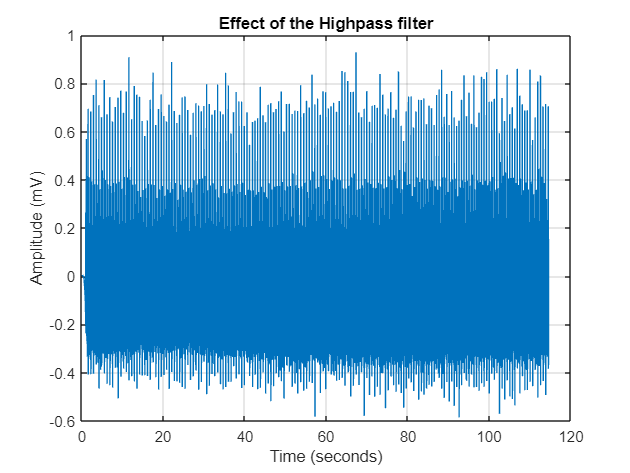

% Apply High-pass filter
ECG_highpass = filter(b_high, a_high, nECG);

figure;
plot(time, ECG_highpass);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the Highpass filter');
grid on; 

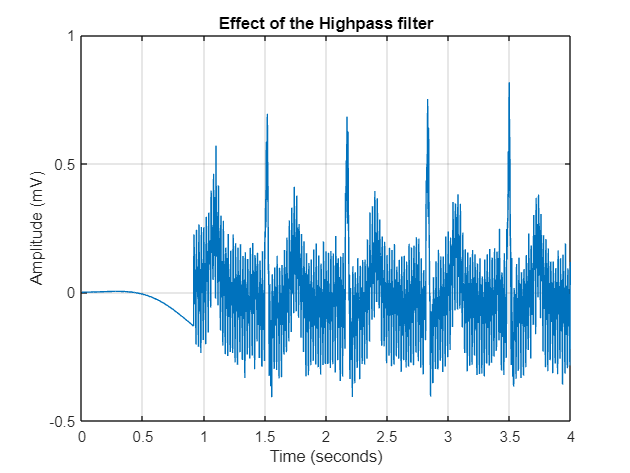



figure;
plot(time(1:2000), ECG_highpass(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the Highpass filter');
grid on; 

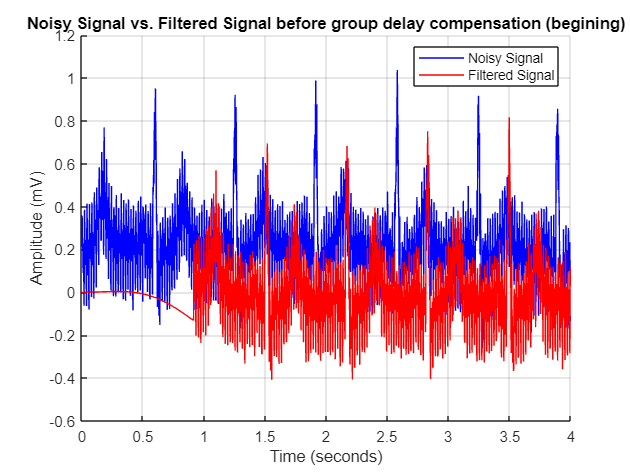

% Plotting the noisy signal and filtered signal for observe the group delay

% Start
figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), ECG_highpass(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal before group delay compensation (begining)');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

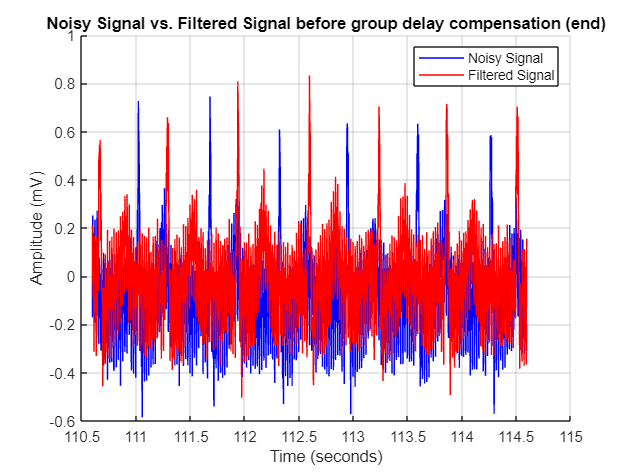


% End
figure;
hold on;  % Keep the current plot
plot(time(length(nECG)-2000:length(nECG)), nECG(length(nECG)-2000:length(nECG)), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(length(nECG)-2000:length(nECG)), ECG_highpass(length(nECG)-2000:length(nECG)), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal before group delay compensation (end)');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

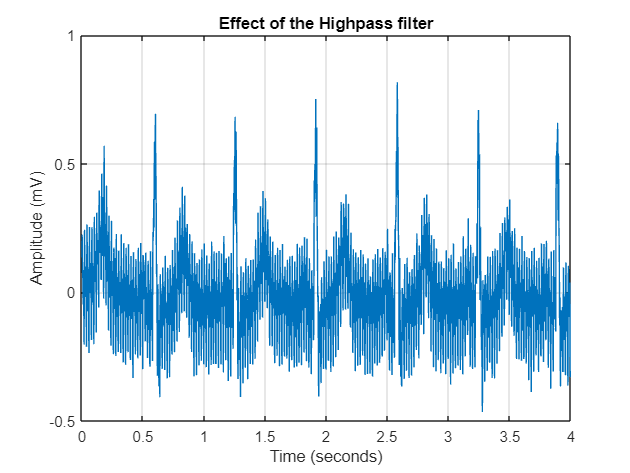

% compensate the group delay
ECG_highpass = circshift(ECG_highpass, -1*ceil(n_h/2));

figure;
plot(time(1:2000), ECG_highpass(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the Highpass filter');
grid on; 

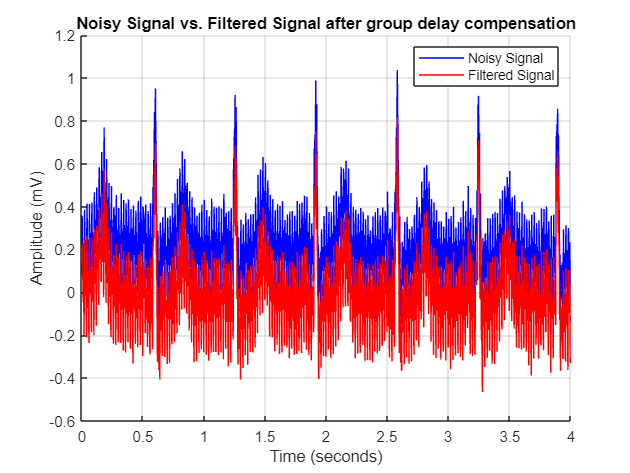



figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), ECG_highpass(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal after group delay compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

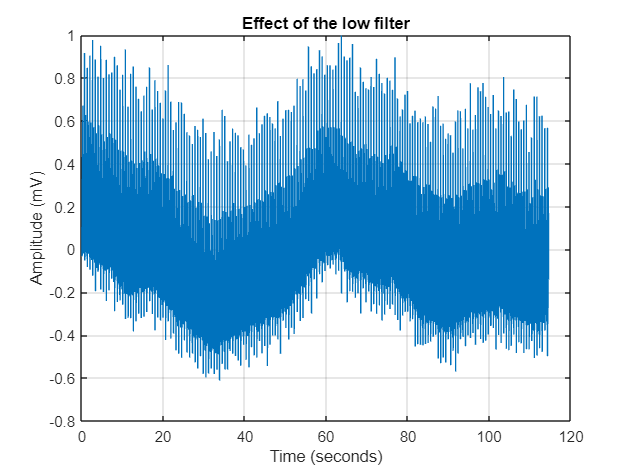

% Apply low-pass filter
ECG_lowpass = filter(b_low, a_low, nECG);

figure;
plot(time, ECG_lowpass);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the low filter');
grid on; 

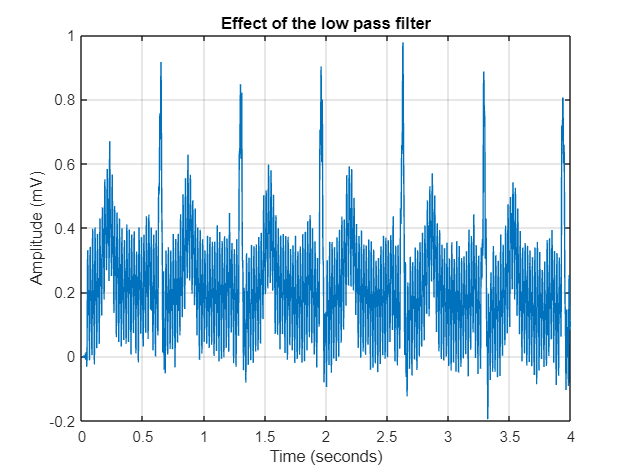



figure;
plot(time(1:2000), ECG_lowpass(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the low pass filter');
grid on; 

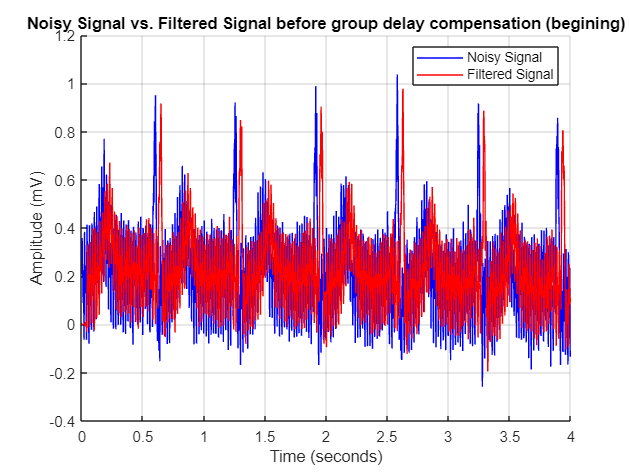

% Plotting the noisy signal and filtered signal for observe the group delay

% Start
figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), ECG_lowpass(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal before group delay compensation (begining)');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

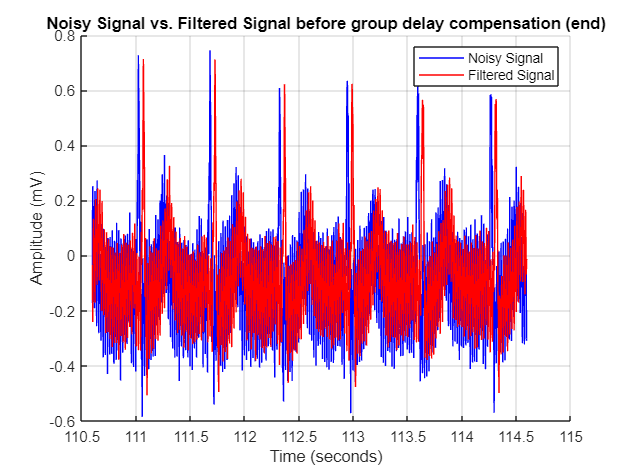


% End
figure;
hold on;  % Keep the current plot
plot(time(length(nECG)-2000:length(nECG)), nECG(length(nECG)-2000:length(nECG)), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(length(nECG)-2000:length(nECG)), ECG_lowpass(length(nECG)-2000:length(nECG)), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal before group delay compensation (end)');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

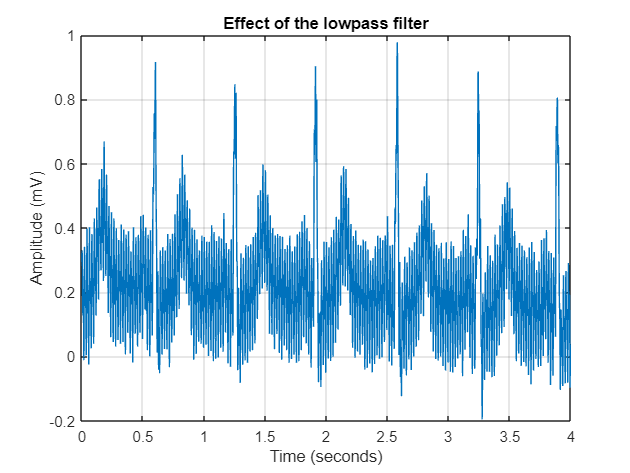

% compensate the group delay
ECG_lowpass = circshift(ECG_lowpass, -1*ceil(n_l/2));

figure;
plot(time(1:2000), ECG_lowpass(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Effect of the lowpass filter');
grid on; 

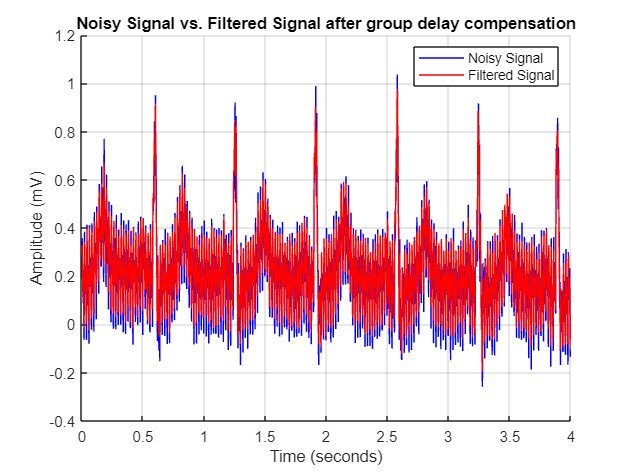



figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), ECG_lowpass(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Noisy Signal vs. Filtered Signal after group delay compensation');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

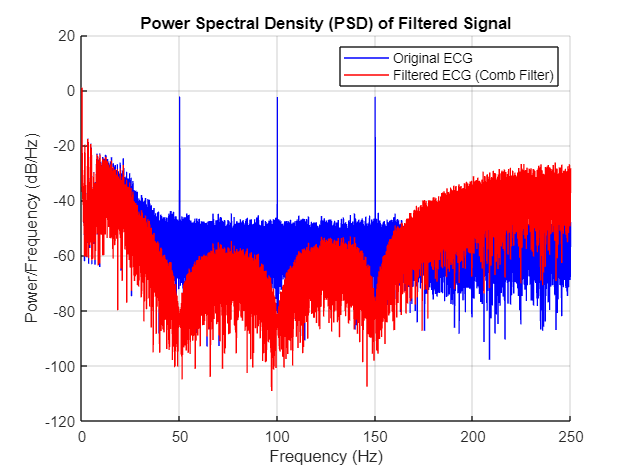

% Apply comb filter
ECG_comb = filter(b_comb, a_comb, nECG);

% Plot the frequency spectrum (PSD)
figure;
hold on;
%periodogram(nECG, window, nfft, fs); 
[pxx_nECG, f_nECG] = periodogram(nECG, window, nfft, fs);
plot(f_nECG, 10*log10(pxx_nECG), 'b-', 'DisplayName', 'PSD of Noisy Signal');

%periodogram(ECG_comb, window, nfft, fs); 
% Calculate and plot PSD of ma3ECG_1
[pxx_ECG_comb, f_ECG_comb] = periodogram(ECG_comb, window, nfft, fs);
plot(f_ECG_comb, 10*log10(pxx_ECG_comb), 'r-', 'DisplayName', 'PSD of Filtered Signal');

legend('Original ECG', 'Filtered ECG (Comb Filter)');
title('Power Spectral Density (PSD) of Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;
hold off;

% Apply all three filters

% Apply High Pass Filter
High_pass_filtered_ECG = filter(b_high, a_high, nECG);
% Compensate Group Delay
High_pass_filtered_ECG = circshift(High_pass_filtered_ECG, -1*ceil(n_h/2));
% Apply Low Pass Filter
Low_pass_filtered_ECG = filter(b_low, a_low, High_pass_filtered_ECG); 
% Compensate Group Delay
Low_pass_filtered_ECG = circshift(Low_pass_filtered_ECG, -1*ceil(n_l/2));
% Apply the comb Filter
FIR_filtered_ECG = filter(b_comb, a_comb, Low_pass_filtered_ECG);
%Compensate Group Delay
FIR_filtered_ECG = circshift(FIR_filtered_ECG, -1*(6/2));
save('FIR_filtered_ECG.mat', 'FIR_filtered_ECG');

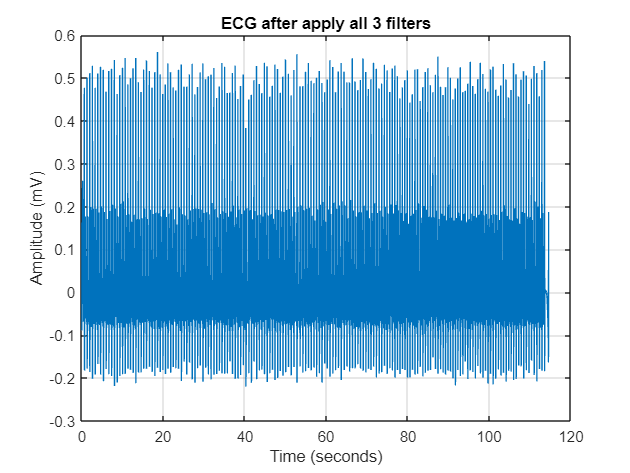

figure;
plot(time, FIR_filtered_ECG);
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('ECG after apply all 3 filters');
grid on; 

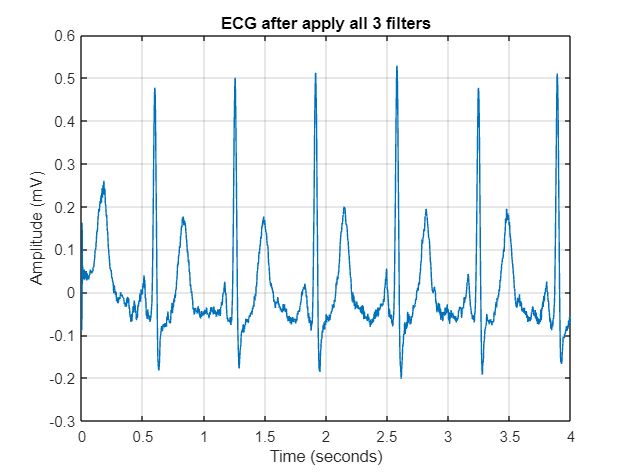


figure;
plot(time(1:2000), FIR_filtered_ECG(1:2000));
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('ECG after apply all 3 filters');
grid on; 

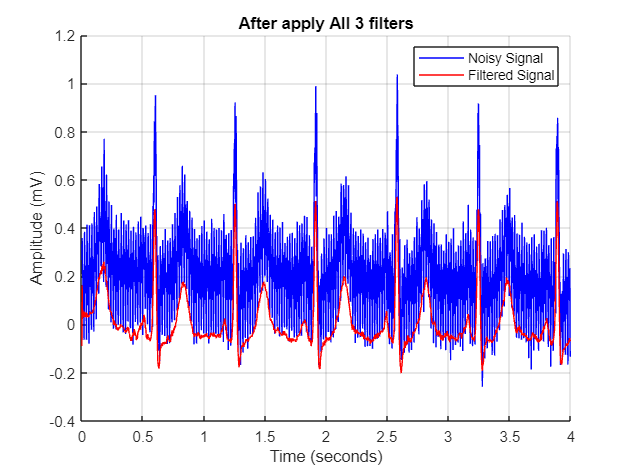

figure;
hold on;  % Keep the current plot
plot(time(1:2000), nECG(1:2000), 'b-', 'DisplayName', 'Noisy Signal');  % Noisy signal in red dashed line
plot(time(1:2000), FIR_filtered_ECG(1:2000), 'r-', 'DisplayName', 'Filtered Signal');  % Filtered signal in solid blue line
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('After apply All 3 filters');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

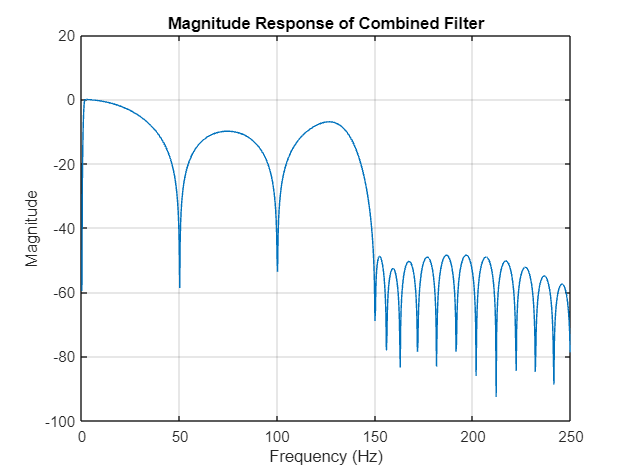

% Frequency response of Combined filter
[H_high, w] = freqz(b_high, a_high, 1024, fs); 
[H_low, ~] = freqz(b_low, a_low, 1024, fs); 
[H_comb, ~] = freqz(b_comb, a_comb, 1024, fs);

H_combined = H_high .* H_low .* H_comb; 
magnitude_combined = 20*log10(abs(H_combined)); 

figure;
plot(w, magnitude_combined);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Response of Combined Filter');
grid on;

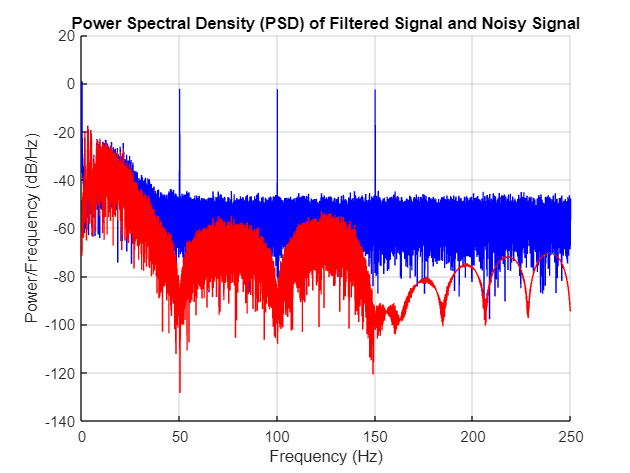

% Power Spectral Density of the Filtered Signal
window_ = rectwin(length(FIR_filtered_ECG)); % to avoid spectral leakage
nfft_ = length(FIR_filtered_ECG); 

% Plot the frequency spectrum (PSD)
figure;
hold on;
%periodogram(FIR_filtered_ECG, window_, nfft_, fs); 

%periodogram(nECG, window, nfft, fs); 
[pxx_nECG, f_nECG] = periodogram(nECG, window, nfft, fs);
plot(f_nECG, 10*log10(pxx_nECG), 'b-', 'DisplayName', 'PSD of Noisy Signal');

%periodogram(ECG_comb, window, nfft, fs); 
% Calculate and plot PSD of ma3ECG_1
[pxx_fECG, f_fECG] = periodogram(FIR_filtered_ECG, window, nfft, fs);
plot(f_fECG, 10*log10(pxx_fECG), 'r-', 'DisplayName', 'PSD of Filtered Signal');

title('Power Spectral Density (PSD) of Filtered Signal and Noisy Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;
hold off;